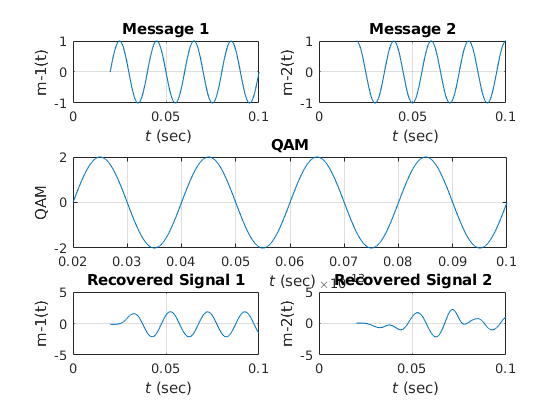

fm = 50;
f = 100*fm;                        % Frquency of carrier wave

t = 1/fm:1/f:5/fm;

m1 = sin(2*pi*fm.*t);
m2 = cos(2*pi*fm.*t);

c1 = cos(2*f*pi*t);
c2 = cos(2*f*pi*t - pi/2);
% ========== %
% MODULATION %
% ========== %
qam =  2*m1.*c1 + 2*m2.*c2;                                   
% ==================================== %
% De-Modulation By Synchoronous Method %
% ==================================== %
dem1 = qam.*c1;
dem2 = qam.*c2;
% ====================
% Filtering Using LPF
% ====================
[b,a] = butter(5,fm*3/f);
rec1 = filter(b,a,dem1);
rec2 = filter(b,a,dem2);
rec1 = rec1 - mean(rec1);
rec2 = rec2 - mean(rec2);
% ================================
% Frequency Responce by fft method
% ================================
m1F = fftshift(fft(m1));                             % Frequency Responce of Message Signal - 1 
m2F = fftshift(fft(m2));                             % Frequency Responce of Message Signal - 2
qamF = fftshift(fft(qam));                           % Frequency Responce of QAM
rec1F = fftshift(fft(rec1));                         % Frequency Responce of Recovered Message Signal - 1
rec2F = fftshift(fft(rec2));                         % Frequency Responce of Recovered Message Signal - 2
F=linspace(-f/2,f/2,length(t));                    %generating the frequency vector
% =============================
% Ploting signal in time domain
% =============================
figure(1);
subplot(3,2,1);
plot(t,m1);
title('Message 1');
xlabel('{\it t} (sec)');
ylabel('m-1(t)');
grid;
subplot(3,2,2);
plot(t,m2);
title('Message 2');
xlabel('{\it t} (sec)');
ylabel('m-2(t)');
grid;
subplot(3,2,[3 4]);
plot(t,qam);
title('QAM');
xlabel('{\it t} (sec)');
ylabel('QAM');
grid;
subplot(3,2,5);
plot(t,rec1);
xlabel('{\it t} (sec)');
ylabel('m-1(t)');
title('Recovered Signal 1');
grid;
subplot(3,2,6);
plot(t,rec2);
xlabel('{\it t} (sec)');
ylabel('m-2(t)');
title('Recovered Signal 2');
grid;

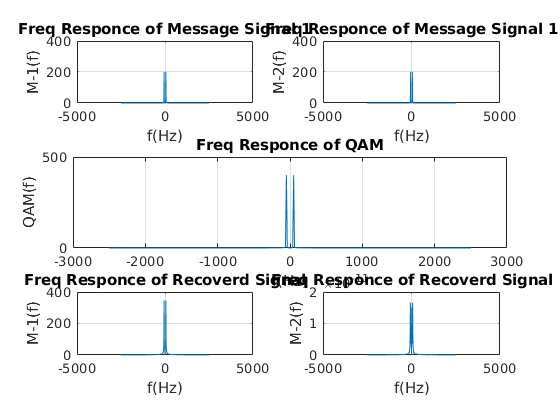

% ================================
% Ploting Freq Responce of Signals
% ================================
figure(2);
subplot(3,2,1);
plot(F,abs(m1F));
title('Freq Responce of Message Signal 1');
xlabel('f(Hz)');
ylabel('M-1(f)');
grid;
subplot(3,2,2);                                         % Ploting Freq Responce of Signals
plot(F,abs(m2F));
title('Freq Responce of Message Signal 1');
xlabel('f(Hz)');
ylabel('M-2(f)');
grid;
subplot(3,2,[3 4]);
plot(F,abs(qamF));
title('Freq Responce of QAM');
xlabel('f(Hz)');
ylabel('QAM(f)');
grid;
subplot(3,2,5);
plot(F,abs(rec1F));
title('Freq Responce of Recoverd Signal');
xlabel('f(Hz)');
ylabel('M-1(f)');
grid;
subplot(3,2,6);
plot(F,abs(rec2F));
title('Freq Responce of Recoverd Signal');
xlabel('f(Hz)');
ylabel('M-2(f)');
grid;